atan(1)/pi*180

ans = 45

alpha=zeros(1,101)

alpha =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tan(pi/2)

ans = 1.6331e+16

theta=3.71/180*pi

theta = 0.0648

v=zeros(1,101)

v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


beta=zeros(1,101)

beta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dt=0.001

dt = 1.0000e-03

J=0.05052

J = 0.0505

r=0.2

r = 0.2000

for k=1:100
    beta(k)=(68.883*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-61.2293*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
    v(k+1)=v(k)+beta(k)*dt;
    alpha(k+1)=alpha(k)+v(k)*dt+beta(k)*dt*dt/2;
end
k=101

k = 101

alpha(end)

ans = 0.0063

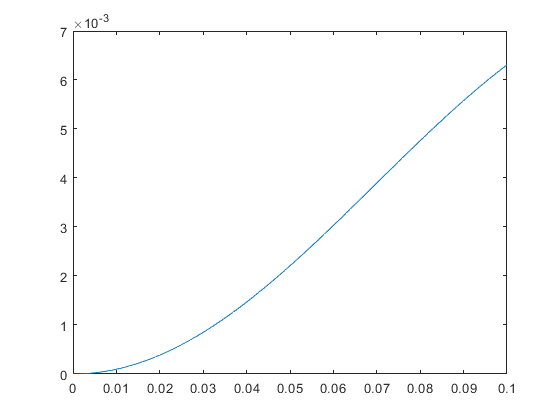

beta(k)=(90*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-80*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
plot(0:0.001:0.1,alpha)

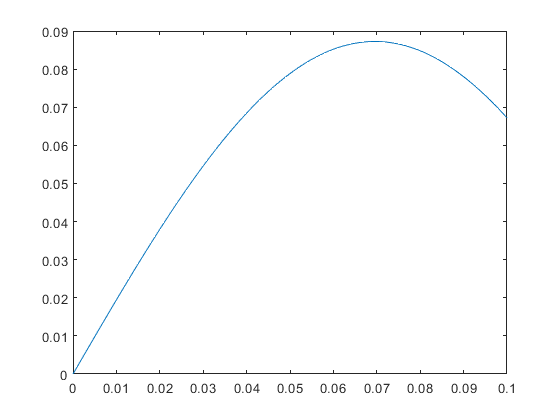

plot(0:0.001:0.1,v)

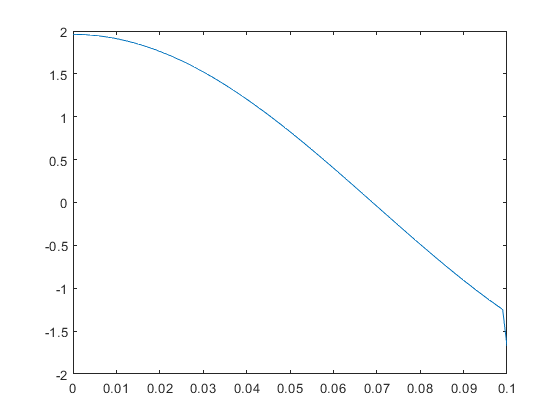

plot(0:0.001:0.1,beta)